Roche de Guzman - ENGG 101 / CSC 102 / MATH 147: Numerical Methods, Hofstra University

# ODEs Second Order: ode23s

    van der Pol equation with t = independent and y = dependent variable

        
$$\frac{d^2 y}{{\textrm{dt}}^2 }-\mu \left(1-y^2 \right)\frac{\textrm{dy}}{\textrm{dt}}+y=0$$


    Let $z=\frac{\textrm{dy}}{\textrm{dt}}$, hence $\frac{\textrm{dz}}{\textrm{dt}}=\frac{d^2 y}{{\textrm{dt}}^2 }$

    System of first order ODEs: 2 equations, 2 dependent (y and z)

        
$$\frac{\textrm{dy}}{\textrm{dt}}=z$$


        
$$\frac{\textrm{dz}}{\textrm{dt}}\;=\mu \left(1-y^2 \right)z-y$$


    Let $Y=\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack$, hence *y = Y(1)* and *z = Y(2)*

clear; clc; close('all'); % clearing fxs

## Given

mu = 1000; % constant
f = @(t,Y) [Y(2); mu*(1-Y(1)^2)*Y(2)-Y(1)]; % ODEs: [dy/dt; dz/dt]= f(t,y,z)
ti = 0; yi = 1; zi = 1; % initial values
tf = 6000; % final t

## Calculations and Results

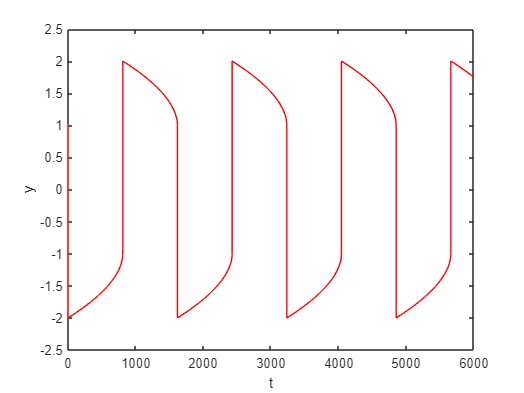

tr = [ti tf]; % t range = [initial t, final t]
Yi = [yi; zi]; % initial Y = [initial y; initial dy/dt]
% numerical
    [t,Y] = ode23s(f,tr,Yi); % solve for the Y matrix
    t = t'; % transpose t vector
    y = Y(:,1)'; % numerical x vector
plot(t,y,'r-','markerfacecolor','r'); % numerical y
xlabel('t'); ylabel('y');